% Load all the audio files
% specify the directory path
folder_path = 'whole recordings'; 

% get information about the .wav files in the directory
wav_files = dir(fullfile(folder_path, '*.wav'));
audNames = {};
% display each .wav file name
for i = 1:length(wav_files)
    audNames{i} = wav_files(i).name(1:8);
end


% Load all motion files
mat_files = dir(fullfile(folder_path, '*.mat'));

txt_files = dir(fullfile('ch1', '*.txt'));

cd 'whole recordings'/

% Load all the files to the workspace
all_audio = struct();
all_motion = struct();
all_motion_smoothed = struct();
for i = 1:length(wav_files)
    all_audio.(audNames{i}) = audioread(wav_files(i).name);
    all_motion.(audNames{i}) = load(mat_files(i).name);
    all_motion_smoothed.(audNames{i}) = movmean(all_motion.(audNames{i}).motion, 5);

end

for i = 1:length(txt_files)
    txtNames{i} = txt_files(i).name(1:10);
end

alumAud = compute_normalized_audiogram('aluminum_0.txt',250000,1000,1,'noiseSeg.txt',0,45);

attenAud = compute_normalized_audiogram('Attenuated.txt',250000,1000,1,'noiseSeg.txt',4,33);
dryAud = compute_normalized_audiogram('DryLeaf4_0.txt',250000,1000,1,'noiseSeg.txt',0,45);
greenAud = compute_normalized_audiogram('GreenLeaf1.txt',250000,1000,1,'noiseSeg.txt',3,39);

nonAud = compute_normalized_audiogram('noObjCombined.txt',250000,1000,1,'noiseSeg.txt',4,43);

[silence,fft_freq] = compute_corrected_audiogram(txt_files(4).name,250000,1000,1,2);

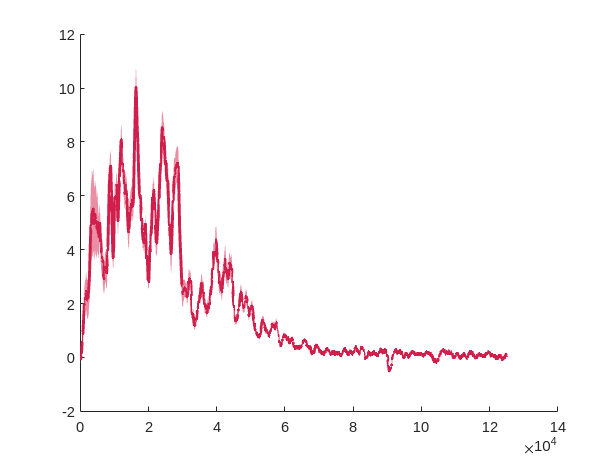

figure;
hold on
plot(alumAud.fft_freq/1000,alumAud.mean_db_spl,'Color',colorBen.aluminum,'LineWidth',2)
x = [alumAud.fft_freq/1000, fliplr(alumAud.fft_freq/1000)]; y = [alumAud.ci_lower, fliplr(alumAud.ci_upper)];
fill(x, y, colorBen.aluminum, 'LineStyle', 'none', 'FaceAlpha', 0.5);
hold on

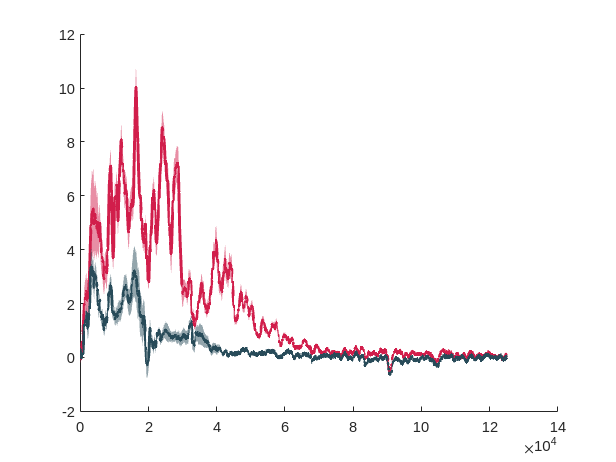


plot(attenAud.fft_freq/1000,attenAud.mean_db_spl,'Color',colorBen.muted,'LineWidth',2)
x = [attenAud.fft_freq/1000, fliplr(attenAud.fft_freq/1000)]; y = [attenAud.ci_lower, fliplr(attenAud.ci_upper)];
fill(x, y, colorBen.muted, 'LineStyle', 'none', 'FaceAlpha', 0.5);

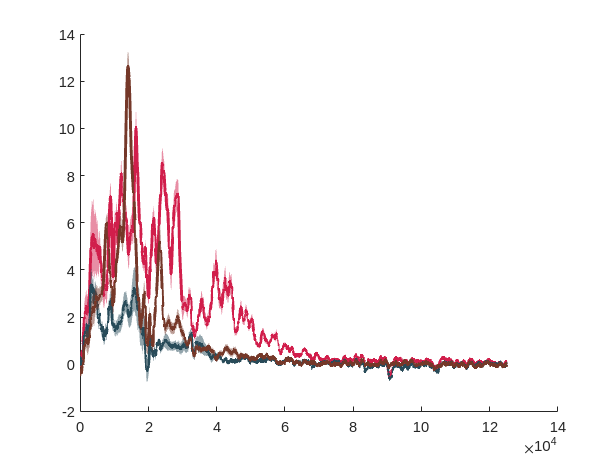


plot(dryAud.fft_freq/1000,dryAud.mean_db_spl,'Color',colorBen.BrownDry,'LineWidth',2)
x = [dryAud.fft_freq/1000, fliplr(dryAud.fft_freq/1000)]; y = [dryAud.ci_lower, fliplr(dryAud.ci_upper)];
fill(x, y, colorBen.BrownDry, 'LineStyle', 'none', 'FaceAlpha', 0.5);

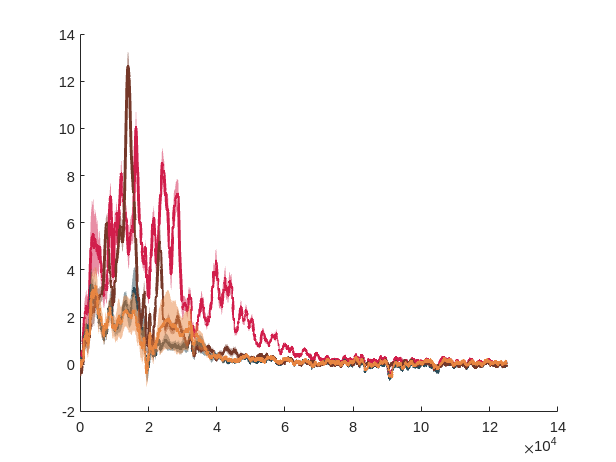


plot(nonAud.fft_freq/1000,nonAud.mean_db_spl,'Color',colorBen.non,'LineWidth',2)
x = [nonAud.fft_freq/1000, fliplr(nonAud.fft_freq/1000)]; y = [nonAud.ci_lower, fliplr(nonAud.ci_upper)];
fill(x, y, colorBen.non, 'LineStyle', 'none', 'FaceAlpha', 0.5);


% plot(greenAud.fft_freq/1000,greenAud.mean_db_spl,'Color',colorBen.blueGreenLeaf,'LineWidth',2)
% x = [greenAud.fft_freq/1000, fliplr(greenAud.fft_freq/1000)]; y = [greenAud.ci_lower, fliplr(greenAud.ci_upper)];
% fill(x, y, colorBen.blueGreenLeaf, 'LineStyle', 'none', 'FaceAlpha', 0.5);

title('Audiogram of whisking against objects normalized to ambient noise')
xlabel('Frequency (kHz)');
    ylabel('Object sound - ambient noise (dbSPL)');
    xlim([2, 55]);
    legend({'Aluminum','','Attenuated foil','','Dry leaf','','No object',''})

figure;
subplot(5,1,1)
plot([1:length(all_motion_smoothed.Aluminum)]/200,all_motion_smoothed.Aluminum/5 - 3,'Color',colorBen.purple)
hold on
plot([1:length(all_audio.Aluminum)]/250000,all_audio.Aluminum*10,'Color',colorBen.green)
xlim([0,5])
ylim([-4 2])
subplot(5,1,2)
plot([1:length(all_motion_smoothed.Attenuat)]/200,all_motion_smoothed.Attenuat/5 - 3,'Color',colorBen.purple)
hold on
plot([1:length(all_audio.Attenuat)]/250000,all_audio.Attenuat*10,'Color',colorBen.green)
xlim([0,5])
ylim([-4 2])
